## Plot2: A panel of 4 plots with each the average annual maximum ndvi

clear all; close all;
load('Entire_region.mat')

RGB=[237,248,251
    204,236,230
    153,216,201
    102,194,164
    65,174,118
    35,139,69
    0,88,36];

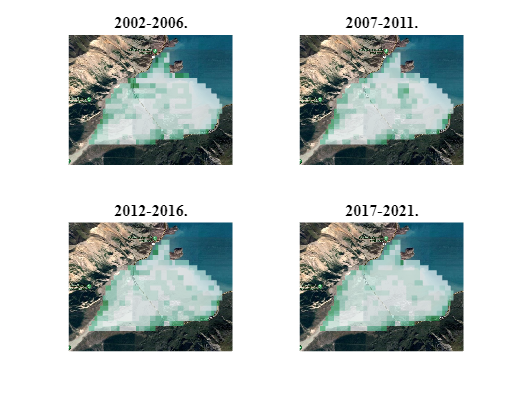

b = 3;
fig=figure(1);
for i = 1:4


    sp = subplot(2,2,i,'Parent',fig);
    img=imread('Yukon_delta.jpg'); 
    image([ -138.447718 -138.570218],[61.033109 60.980258], img);
    hold('on');   

    t = T{:,b:b+4}';
    mean_max_ndvi = mean(t);
    mean_max_ndvi = mean_max_ndvi';


    A = ~isnan(ndvi(:,:, 15));
    Z_mean_max_ndvi = []; % nrXnc matrix
    x = 0;
    for j = 1:nc
        z_mean_max_ndvi_col = [];
        indx = find(A(:,j)>0);
        start_indx = indx(1);
        end_indx = indx(end);
        z_mean_max_ndvi_col(1:start_indx-1) = NaN;
        z_mean_max_ndvi_col(indx)=mean_max_ndvi(x+1: x+length(indx));
        z_mean_max_ndvi_col(end_indx+1:nr) = missing;
        x = x+length(indx);
        Z_mean_max_ndvi = [Z_mean_max_ndvi z_mean_max_ndvi_col'];
    end
    clear A; clear end_indx; clear start_indx; clear i; 
    clear x; clear z_mean_max_ndvi_col; clear mean_max_ndvi; clear indx

    [nr,nc]=size(Z_mean_max_ndvi);
    s= pcolor([X(:,1);nan],[Y(1,:), nan],[Z_mean_max_ndvi nan(nr,1); nan(1,nc+1)]' );
    s.EdgeColor = 'none' ;
    s.FaceAlpha = 0.7;
    
    c = colorbar; 
    caxis(sp, [0 0.7]);
    colormap(RGB./255);
    
    %xlabel("Longitude",'FontName', 'Dialog'); 
    %ylabel("Latitude",'FontName', 'Dialog'); 
    formatSpec = '%d-%d.';
    A1 = 1999+b;
    A2 = 1999+b+4;
    str = sprintf(formatSpec,A1,A2);   
    title(str,'FontName', 'Dialog')
    
    set(gca, 'xDir', 'reverse') 
    set(gca,'XAxisLocation','top','YAxisLocation','right','ydir','reverse');
    camroll(180)
    axis off
    colorbar off
    hold off;
    clear c; clear s; clear t; clear Z_mean_max_ndvi;

    b=b+5;

end

clear b; clear i; clear img; clear j;clear str; clear formatSpec; clear A1;
clear A2


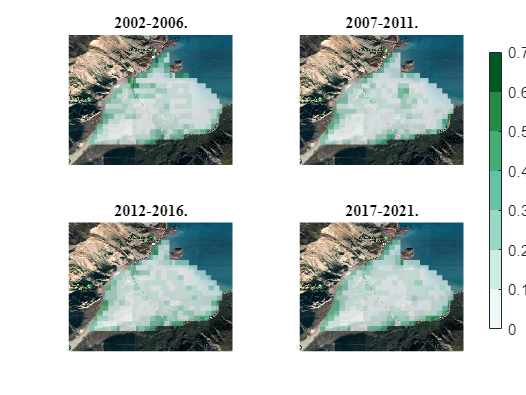

h = axes(fig,'visible','off'); 
h.Title.Visible = 'off';
h.XLabel.Visible = 'on';
h.YLabel.Visible = 'on';

c = colorbar(h,'Position',[0.93 0.168 0.022 0.7]);  % attach colorbar to h
colormap(RGB./255);
c.Label.String = 'Mean Annual-Maximum ndvi';
c.Label.FontName = 'Dialog';
c.Label.FontSize = 10;
caxis(h,[0,0.7]); 

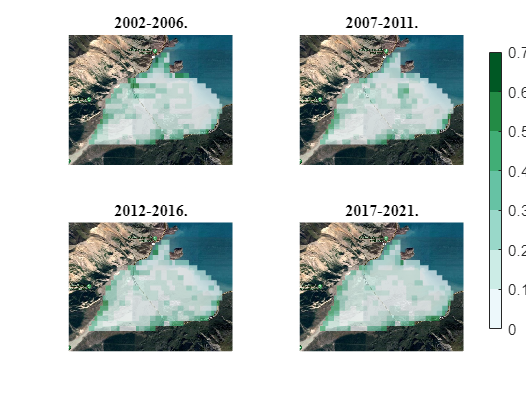

saveas(gcf,'Published_Plots\Figure_6.pdf')